## **Aggregation - Multiple Data Points**

DT_Agg_Multiple = readtable("DT_Aggregate_Multiple_Data.csv", 'VariableNamingRule','preserve');
Conv_Agg_Multiple = readtable("Conv_Aggregate_Multiple_Data.csv",'VariableNamingRule','preserve');
Local_Agg_Multiple = readtable("Local_Conv_Aggregate_Multiple_Data.csv", 'VariableNamingRule','preserve');

### Aggregation - Latency

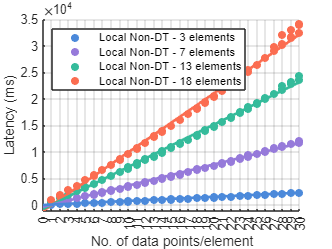

DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerFaceAlpha",1,MarkerFaceColor="#35BB9B");
hold on;
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#FB6D51");
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#646C77");
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#D94452");

Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerFaceAlpha",1,MarkerFaceColor="#646C77");
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#D94452");
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#35BB9B");
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#FB6D51");

Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 3,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#4B89DA");
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 7,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#967ADA");
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 13,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#35BB9B");
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 18,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#FB6D51");

hold off
legend('Local Non-DT - 3 elements','Local Non-DT - 7 elements','Local Non-DT - 13 elements','Local Non-DT - 18 elements','Location','northwest')%,'Non-DT - 3 elements','Non-DT - 18 elements','Location','northwest')%,'Local Non-DT - 3 elements','Local Non-DT - 18 elements','Location','northwest');
set(gca,'xtick',linspace(0,30,31))
grid on
ylabel("Latency (ms)")
xlabel("No. of data points/element")
h = lsline;
%set(h(4),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
%set(h(3),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);

set(h(4),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

### Aggregation - RAM Usage

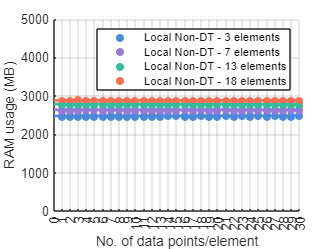

DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B"), hold on
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#646C77")
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#D94452")

Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#646C77"), hold on
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#D94452")
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B")
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")

Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 3,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#4B89DA"), hold on
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 7,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#967ADA")
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 13,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B")
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 18,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")

hold off
legend('Local Non-DT - 3 elements','Local Non-DT - 7 elements','Local Non-DT - 13 elements','Local Non-DT - 18 elements','Location','northeast')%,'Non-DT - 3 elements','Non-DT - 18 elements','Location','northwest')%,'Local Non-DT - 3 elements','Local Non-DT - 18 elements','Location','northwest');
set(gca,'xtick',linspace(0,30,31))
ylim([0 5000])
grid on
ylabel("RAM usage (MB)")
xlabel("No. of data points/element")
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(4),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
%set(h(3),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
set(h(4),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

### Aggregation - CPU Usage

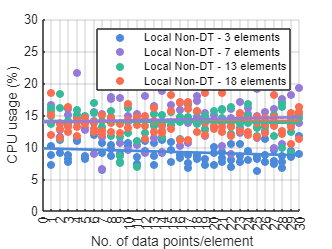

DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#35BB9B"), hold on
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#646C77")
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#D94452")

Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 3,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#646C77"), hold on
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 7,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#D94452")
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 13,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#35BB9B")
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 18,:);
%scatter(Conv_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")

Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 3,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#4B89DA"), hold on
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 7,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#967ADA")
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 13,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#35BB9B")
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 18,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")

hold off
legend('Local Non-DT - 3 elements','Local Non-DT - 7 elements','Local Non-DT - 13 elements','Local Non-DT - 18 elements')%,'Non-DT - 3 elements','Non-DT - 18 elements','Location','northwest')%,'Local Non-DT - 3 elements','Local Non-DT - 18 elements','Location','northwest');
set(gca,'xtick',linspace(0,30,31))
ylim([0 30])
grid on
ylabel("CPU usage (%)")
xlabel("No. of data points/element")
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(4),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
%set(h(3),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
set(h(4),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

## **Aggregation - Single Data Points**

DT_Agg_Single = readtable("DT_Aggregate_Single_Data.csv", 'VariableNamingRule','preserve');
Conv_Agg_Single = readtable("Conv_Aggregate_Single_Data.csv",'VariableNamingRule','preserve');
Local_Agg_Single = readtable("Local_Conv_Aggregate_Single_Data.csv", 'VariableNamingRule','preserve');

### Aggregation - Latency

scatter(DT_Agg_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#35BB9B"), hold on
%scatter(Conv_Agg_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#FB6D51")
scatter(Local_Agg_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#646C77")
hold off
legend('DT', 'Non-DT','Location','northwest')%, 'Local Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
ylabel("Latency (ms)")
xlabel("No. of elements")
xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### Aggregation - RAM Usage

scatter(DT_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled",MarkerFaceColor="#646C77")
hold off
legend('DT', 'Non-DT','Location','northwest')%, 'Local Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
ylim([0 5000])
ylabel("RAM usage (MB)")
xlabel("No. of elements")
xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### Aggregation - CPU Usage

scatter(DT_Agg_Single,"Number of DTs","Total CPU Usage (%)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Agg_Single,"Number of DTs","CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Agg_Single,"Number of DTs","CPU Usage (%)","filled",MarkerFaceColor="#646C77")
hold off
legend('DT', 'Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
ylim([0 30])
ylabel("CPU usage (%)")
xlabel("No. of elements")
xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

## **Multiple DTIs - Multiple Data Points**

DT_Mul_DTI_Multiple = readtable("DT_Multiple_DTI_Multiple_Data.csv", 'VariableNamingRule','preserve');
Conv_Mul_DTI_Multiple = readtable("Conv_Multiple_DTI_Multiple_Data.csv",'VariableNamingRule','preserve');
Local_Mul_DTI_Multiple = readtable("Local_Conv_Multiple_DTI_Multiple_Data.csv", 'VariableNamingRule','preserve');

### **Multiple DTIs** - Latency

DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#35BB9B"), hold on
DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#FB6D51")

Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#646C77")
Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#D94452")

Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 3,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#4B89DA")
Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 18,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled", "MarkerFaceAlpha",1,MarkerFaceColor="#967ADA"), hold off

hold off
legend('DT - 1 building','DT - 13 buildings','Non-DT - 1 building','Non-DT - 13 buildings','Location','northwest')%,'Local Non-DT - 3 elements','Local Non-DT - 18 elements','Location','northwest')
set(gca,'xtick',linspace(0,30,31))
grid on
ylabel("Latency (ms)")
xlabel("No. of data points/element")
h = lsline;
set(h(4),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
set(h(2),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
%set(h(2),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

### **Multiple DTIs** - RAM Usage

DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B"), hold on
DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")

Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#646C77")
Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#D94452")

Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 3,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#4B89DA")
Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 18,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#967ADA"), hold off

hold off
legend('DT system - 1 building','DT system - 13 buildings','Non-DT system - 1 building','Non-DT system - 13 buildings','Location','southeast')%,'Local Non-DT system - 3 elements','Local Non-DT system - 18 elements')
set(gca,'xtick',linspace(0,30,31))
ylim([0 5000])
grid on
ylabel("RAM usage (MB)")
xlabel("No. of data points/element")
h = lsline;
set(h(4),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
set(h(2),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
%set(h(2),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

### **Multiple DTIs** - CPU Usage

DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#35BB9B"), hold on
DT_Mul_DTI_Multiple_Process = DT_Mul_DTI_Multiple(DT_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(DT_Mul_DTI_Multiple_Process,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")

Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 3,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#646C77")
Conv_Mul_DTI_Multiple_Process = Conv_Mul_DTI_Multiple(Conv_Mul_DTI_Multiple.("Number of DTs") == 18,:);
scatter(Conv_Mul_DTI_Multiple_Process,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#D94452")

Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 3,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#4B89DA")
Local_Mul_DTI_Multiple_Process = Local_Mul_DTI_Multiple(Local_Mul_DTI_Multiple.("Number of DTs") == 18,:);
%scatter(Local_Mul_DTI_Multiple_Process,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#967ADA"), hold off

hold off
legend('DT system - 1 building','DT system - 13 buildings','Non-DT system - 1 building','Non-DT system - 13 buildings')%,'Local Non-DT system - 3 elements','Local Non-DT system - 18 elements')
set(gca,'xtick',linspace(0,30,31))
ylim([0 100])
grid on
ylabel("CPU usage (%)")
xlabel("No. of data points/element")
h = lsline;
set(h(4),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(3),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
set(h(2),"Color","#646C77",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#D94452",'HandleVisibility','off','LineWidth',2);
%set(h(2),"Color","#4B89DA",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#967ADA",'HandleVisibility','off','LineWidth',2);

## **Multiple DTIs - Single Data Points**

DT_Mul_DTI_Single = readtable("DT_Multiple_DTI_Single_Data.csv", 'VariableNamingRule','preserve');
Conv_Mul_DTI_Single = readtable("Conv_Multiple_DTI_Single_Data.csv",'VariableNamingRule','preserve');
Local_Mul_DTI_Single = readtable("Local_Conv_Multiple_DTI_Single_Data.csv", 'VariableNamingRule','preserve');

### **Multiple DTIs** - Latency

scatter(DT_Mul_DTI_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#35BB9B"), hold on
%scatter(Conv_Mul_DTI_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#FB6D51")
scatter(Local_Mul_DTI_Single,"Number of DTs","Total Time Taken","filled",MarkerFaceColor="#646C77")
hold off
legend('DT', 'Non-DT','Location','northwest')%, 'Local Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
grid on
ylabel("Latency (ms)")
xlabel("No. of elements")
%xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### **Multiple DTIs** - RAM Usage

scatter(DT_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Agg_Single,"Number of DTs","Total RAM Usage (MB)","filled","MarkerEdgeColor","flat")
hold off
legend('DT', 'Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
ylim([0 5000])
ylabel("RAM usage (MB)")
xlabel("No. of elements")
xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### **Multiple DTIs** - CPU Usage

scatter(DT_Mul_DTI_Single,"Number of DTs","Total CPU Usage (%)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Mul_DTI_Single,"Number of DTs","CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Mul_DTI_Single,"Number of DTs","CPU Usage (%)","filled","MarkerEdgeColor","flat")
hold off
legend('DT', 'Non-DT')
grid on
set(gca,'xtick',linspace(0,20,21))
ylim([0 100])
ylabel("CPU usage (%)")
xlabel("No. of elements")
xlim([0 19])
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

## **Single DTI - Multiple Data Points**

DT_Single_DTI_Multiple = readtable("DT_Single_DTI_Multiple_Data.csv", 'VariableNamingRule','preserve');
Conv_Single_DTI_Multiple = readtable("Conv_Single_DTI_Multiple_Data.csv",'VariableNamingRule','preserve');
Local_Single_DTI_Multiple = readtable("Local_Conv_Single_DTI_Multiple_Data.csv", 'VariableNamingRule','preserve');

### **Single DTI** - Latency

scatter(DT_Single_DTI_Multiple,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Single_DTI_Multiple,"Number of Data Points","Total Time Taken","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Single_DTI_Multiple,"Number of Data Points","Total Time Taken","filled")

hold off
legend('DT','Non-DT','Location','northwest')
set(gca,'xtick',linspace(0,30,31))
grid on
ylabel("Latency (ms)")
xlabel("No. of data points")
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### **Single DTI** - RAM Usage

scatter(DT_Single_DTI_Multiple,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Single_DTI_Multiple,"Number of Data Points","Total RAM Usage (MB)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Single_DTI_Multiple,"Number of Data Points","Total Time Taken","filled")

hold off
legend('DT','Non-DT')
set(gca,'xtick',linspace(0,30,31))
ylim([0 5000])
grid on
ylabel("RAM usage (MB)")
xlabel("No. of data points")
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

### **Single DTI** - CPU Usage

scatter(DT_Single_DTI_Multiple,"Number of Data Points","Total CPU Usage (%)","filled",MarkerFaceColor="#35BB9B"), hold on
scatter(Conv_Single_DTI_Multiple,"Number of Data Points","CPU Usage (%)","filled",MarkerFaceColor="#FB6D51")
%scatter(Local_Single_DTI_Multiple,"Number of Data Points","Total Time Taken","filled")

hold off
legend('DT','Non-DT')
set(gca,'xtick',linspace(0,30,31))
ylim([0 30])
grid on
ylabel("CPU usage (%)")
xlabel("No. of data points")
h = lsline;
set(h(2),"Color","#35BB9B",'HandleVisibility','off','LineWidth',2);
set(h(1),"Color","#FB6D51",'HandleVisibility','off','LineWidth',2);
%set(h(1),"Color","#646C77",'HandleVisibility','off','LineWidth',2);

## **Single DTI - Single Data Points**

DT_Single_DTI_Single = readtable("DT_Single_DTI_Single_Data.csv", 'VariableNamingRule','preserve');
Conv_Single_DTI_Single = readtable("Conv_Single_DTI_Single_Data_File.csv",'VariableNamingRule','preserve');
Local_Single_DTI_Single = readtable("Local_Conv_Single_DTI_Single_Data_File.csv", 'VariableNamingRule','preserve');

### **Single DTI** - Latency

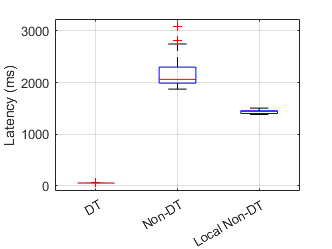

x = [DT_Single_DTI_Single.("Total Time Taken");Conv_Single_DTI_Single.("Total Time Taken");Local_Single_DTI_Single.("Total Time Taken")];
g = [ones(size(DT_Single_DTI_Single.("Total Time Taken"))); 2*ones(size(Conv_Single_DTI_Single.("Total Time Taken"))); 3*ones(size(Local_Single_DTI_Single.("Total Time Taken")))];
boxplot(x,g)
grid on
set(gca,'XTickLabel',{'DT','Non-DT', 'Local Non-DT'})
ylabel('Latency (ms)')

### **Single DTI** - RAM Usage

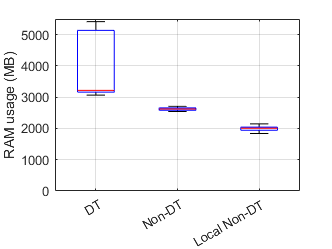

x = [DT_Single_DTI_Single.("Total RAM Usage (MB)");Conv_Single_DTI_Single.("Total RAM Usage (MB)");Local_Single_DTI_Single.("Total RAM Usage (MB)")];
g = [ones(size(DT_Single_DTI_Single.("Total RAM Usage (MB)"))); 2*ones(size(Conv_Single_DTI_Single.("Total RAM Usage (MB)"))); 3*ones(size(Local_Single_DTI_Single.("Total RAM Usage (MB)")))];
boxplot(x,g)
grid on
set(gca,'XTickLabel',{'DT','Non-DT','Local Non-DT'})
ylabel('RAM usage (MB)')
ylim([0 5500])

### **Single DTI** - CPU Usage

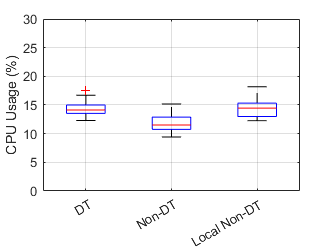

x = [DT_Single_DTI_Single.("Total CPU Usage (%)");Conv_Single_DTI_Single.("CPU Usage (%)");Local_Single_DTI_Single.("CPU Usage (%)")];
g = [ones(size(DT_Single_DTI_Single.("Total CPU Usage (%)"))); 2*ones(size(Conv_Single_DTI_Single.("CPU Usage (%)"))); 3*ones(size(Local_Single_DTI_Single.("CPU Usage (%)")))];
boxplot(x,g)
grid on
set(gca,'XTickLabel',{'DT','Non-DT','Local Non-DT'})
ylabel('CPU Usage (%)')
ylim([0 30])